% 1. Define the 3-variable function (Example: x^2 + y^2 - z > 0)
Lambda = 0.0004;
mu = Lambda;
gamma = 1;
alpha_i = 0;

H = @(epsilon, alpha_s, beta) Hopf_surface(Lambda, mu, beta, gamma, epsilon, alpha_i, alpha_s);
%H = @(epsilon, alpha_s, beta) epsilon.^2 + alpha_s.^2 - beta.^2.*alpha_s;

% 2. Create a 3-D grid
num_epsilon_vals = 250;
num_alpha_s_vals = 250;
num_beta_vals = 1000;
[x, y, z] = meshgrid(linspace(0, 1, num_epsilon_vals), linspace(0, 1, num_alpha_s_vals), linspace(0, 250, num_beta_vals));
V = H(x, y, z);
min(V(:))

ans = -3.0877e+07

max(V(:))

ans = 0.0065

% 3. Plot the boundary (isosurface) where the function equals zero
fig = figure("Position", [0 0 400 300]);

surf = isosurface(x, y, z, V, 0)

surf = struct with fields:
    vertices: [391863×3 double]
       faces: [781177×3 double]


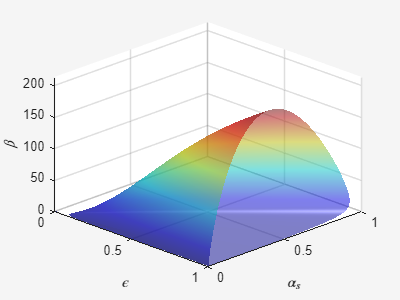


% 3. Extract Z-coordinates of vertices
z_coords = surf.vertices(:,3);

% 4. Map Z-coordinates to colormap
cm = jet(256); % Choose your colormap (e.g., jet, parula, hot)
c_min = min(z_coords);
c_max = max(z_coords);
c_index = round((z_coords - c_min) / (c_max - c_min) * 255) + 1;
surf.facevertexcdata = cm(c_index,:);

% 5. Plot the patch object
p = patch(surf, 'FaceColor', 'interp', 'EdgeColor', 'none');

% 4. Format the plot for better visibility
isonormals(x, y, z, V, p);
p.EdgeColor = 'none';
p.FaceAlpha = 0.5;
p.AmbientStrength = 0.67;
view(45, 30);
camlight; 
lighting gouraud;
xlabel("$\epsilon$", "Interpreter", "latex", "Rotation", 0); 
ylabel("$\alpha_s$", "Interpreter", "latex", "Rotation", 0); 
zlabel("$\beta$", "Interpreter", "latex", "Rotation", 0);

grid on;

theme(fig, "light");

function H = Hopf_surface(Lambda, mu, beta, gamma, epsilon, alpha_i, alpha_s)
    % Hardcoded equations for the endemic equilibrium
    A2 = -epsilon.*beta.*(mu + alpha_i);
    A1 = Lambda.*epsilon.*beta + epsilon.*gamma.*mu - ((mu + gamma + alpha_i) ./ beta) .* (beta.*(alpha_s + mu) + epsilon.*beta.*mu);
    A0 = Lambda.*(alpha_s + mu) - ((mu + gamma + alpha_i) ./ beta) .* mu.*(alpha_s + mu);

    I = (-A1 - sqrt(A1.^2 - 4.*A0.*A2)) ./ (2.*A2);
    Ss = (gamma.*I) ./ (epsilon.*beta.*I + alpha_s + mu);

    % Return H
    term1 = epsilon.*alpha_s.*(mu + alpha_s).*beta.*Ss;
    term2 = ((epsilon.*beta.*I + mu + alpha_s).^2).*(beta.*I + mu);
    term3 = (epsilon.*beta.*I + mu + beta.*I).*(1 - epsilon).*(mu + alpha_s).*beta.*Ss;
    term4 = (epsilon.*beta.*I + mu + alpha_s).*((beta.*I + mu).^2);
    term5 = (beta.*I + mu).*(mu + alpha_i).*beta.*I;
    H = term1 - term2 - term3 - term4 - term5;
end

% Calculate the location of the endeimc equilibrium analytically using the
% equations in the Supplemental Material of Saad-Roy et al. (2023)
function x_star = get_chadi_model_EE(Lambda, mu, beta, gamma, epsilon, alpha_i, alpha_s)
    A2 = -epsilon.*beta.*(mu + alpha_i);
    A1 = Lambda.*epsilon.*beta + epsilon.*gamma.*mu - ((mu + gamma + alpha_i) ./ beta) .* (beta.*(alpha_s + mu) + epsilon.*beta.*mu);
    A0 = Lambda.*(alpha_s + mu) - ((mu + gamma + alpha_i) ./ beta) .* mu.*(alpha_s + mu);

    I_star = (-A1 - sqrt(A1.^2 - 4.*A0.*A2)) ./ (2.*A2);
    Ss_star = (gamma.*I_star) ./ (epsilon.*beta.*I_star + alpha_s + mu);
    Sp_star = (mu + gamma + alpha_i)./beta - epsilon.*Ss_star;

    x_star = [Sp_star; I_star; Ss_star];
end